dialogbox

% Create a question dialog box for img capture
answer = questdlg('Capture image:', ...
                 'Boolean Input', ...
                 'Yes', 'No', 'Yes');
                 
% Handle the response
switch answer
    case 'Yes'
        myVariable = true;
    case 'No'
        myVariable = false;
    otherwise
        % Handle case where user closes dialog without selecting
        myVariable = []; % or some default value
end

click pic

if myVariable==true
addpath('C:\Users\admin\OneDrive - North Carolina State University\Dr. Nitin Sharma\visual servo control\mex-wrapper')
Simulink.importExternalCTypes('C:\Users\admin\OneDrive - North Carolina State University\Dr. Nitin Sharma\visual servo control\kortex_wrapper_data.h');
gen3Kinova = kortex();
gen3Kinova.ip_address = '192.168.1.10';
 
isOk = gen3Kinova.CreateRobotApisWrapper();
if isOk
   disp('You are connected to the robot!'); 
else 
   error('Failed to establish a valid connection!'); 
end

You are connected to the robot!





% === Setup ===
timestamp = datestr(now, 'yyyymmdd_HHMMSS');  % Unique timestamp
imageFilename = strcat("kinova_image_", timestamp, ".png");
poseFilename = "kinova_pose.mat";  % Fixed filename to append pose data


% === Capture Image from GStreamer ===
system('start /B gst-launch-1.0 rtspsrc location=rtsp://192.168.1.10/color latency=30 ! decodebin ! videoconvert ! jpegenc ! filesink location="C:/Users/admin/OneDrive - North Carolina State University/Dr. Nitin Sharma/visual servo control/temp_image.png"');
pause (30)
% Read and store the captured image
img = imread('temp_image.png');
imwrite(img, imageFilename);  % Save image with timestamp
delete('temp_image.png');  % Remove temp image

% === Get Joint Angles ===
[~, ~, actuatorFb, ~] = gen3Kinova.SendRefreshFeedback();  
jointAngles = actuatorFb.position;  % Extract joint positions (angles in degrees)
jointAngles = jointAngles * pi / 180;  % Convert to radians

% === Get End Effector Pose ===
% endEffectorPose = getTransform(gen3Kinova, jointAngles', 'EndEffector_Link');  % Adjust link name if needed
[~,~, actuatorFb, ~] = gen3Kinova.SendRefreshFeedback();
jointAngles=(actuatorFb.position)'
% === Save Data with Timestamp ===
newData.timestamp = timestamp;
newData.jointAngles = jointAngles;
% newData.endEffectorPose = endEffectorPose;
newData.imageFilename = imageFilename;

% Load existing data if file exists
if isfile(poseFilename)
    oldData = load(poseFilename);
    
    % Append new data
    oldData.data = [oldData.data; newData];  % Append new struct to existing array
else
    oldData.data = newData;  % Create new data entry
end

% Save updated data structure
save(poseFilename, '-struct', 'oldData');

disp("Image and pose data saved with timestamp.");


h=msgbox('Move kinova_pose.mat to Caliberation_Data', 'Action Required', 'help');
uiwait(h);

end



jointAngles =     6.0919
   21.3786
  347.2936
   78.9124
  186.3760
  269.7819
   98.6171


Image and pose data saved with timestamp.


load robot

clc;
clear all;
close all;

% Load the robot model from a .mat file as a rigidBodyTree object
gen3 = loadrobot("kinovaGen3");
gen3.DataFormat = 'column';

save test angle

addpath('C:\Users\admin\OneDrive - North Carolina State University\Dr. Nitin Sharma\visual servo control')
jointConfiguration = load("Caliberation_Data/kinova_pose.mat");
jointPositionsRad_row = {jointConfiguration.data.jointAngles};


data = jointPositionsRad_row(1,end);  % Example data
save('C:\Users\admin\OneDrive - North Carolina State University\Dr. Nitin Sharma\visual servo control\Test_Angle.mat', 'data');  % Saves variable 'data' into myData.mat
img_row={jointConfiguration.data.imageFilename};
img_row_selected=img_row{end};
img_location=strcat('C:\Users\admin\OneDrive - North Carolina State University\Dr. Nitin Sharma\visual servo control\Caliberation_Data\',img_row_selected);
img=imread(img_location);
imwrite(img,'C:\Users\admin\OneDrive - North Carolina State University\Dr. Nitin Sharma\visual servo control\Test_Img.png');

define initial pose


% Define initial pose by specifying the joint values (in radians) at ['Shoulder_Link', 'HalfArm1_Link',	'HalfArm2_Link', 'ForeArm_Link', 'Wrist1_Link',	'Wrist2_Link','Bracelet_Link']
jointConfiguration = load("Caliberation_Data/kinova_pose.mat");
jointPositionsDeg = {jointConfiguration.data.jointAngles};
jointPositionsDeg_row = {jointConfiguration.data.jointAngles};
testPose_Deg= jointPositionsDeg_row(1,end)';
testPose_Radmat=deg2rad(cell2mat(testPose_Deg));
% Get the end effector transform

endEffectorTransf  = getTransform(gen3,testPose_Radmat,'EndEffector_Link');

initialize simulation env

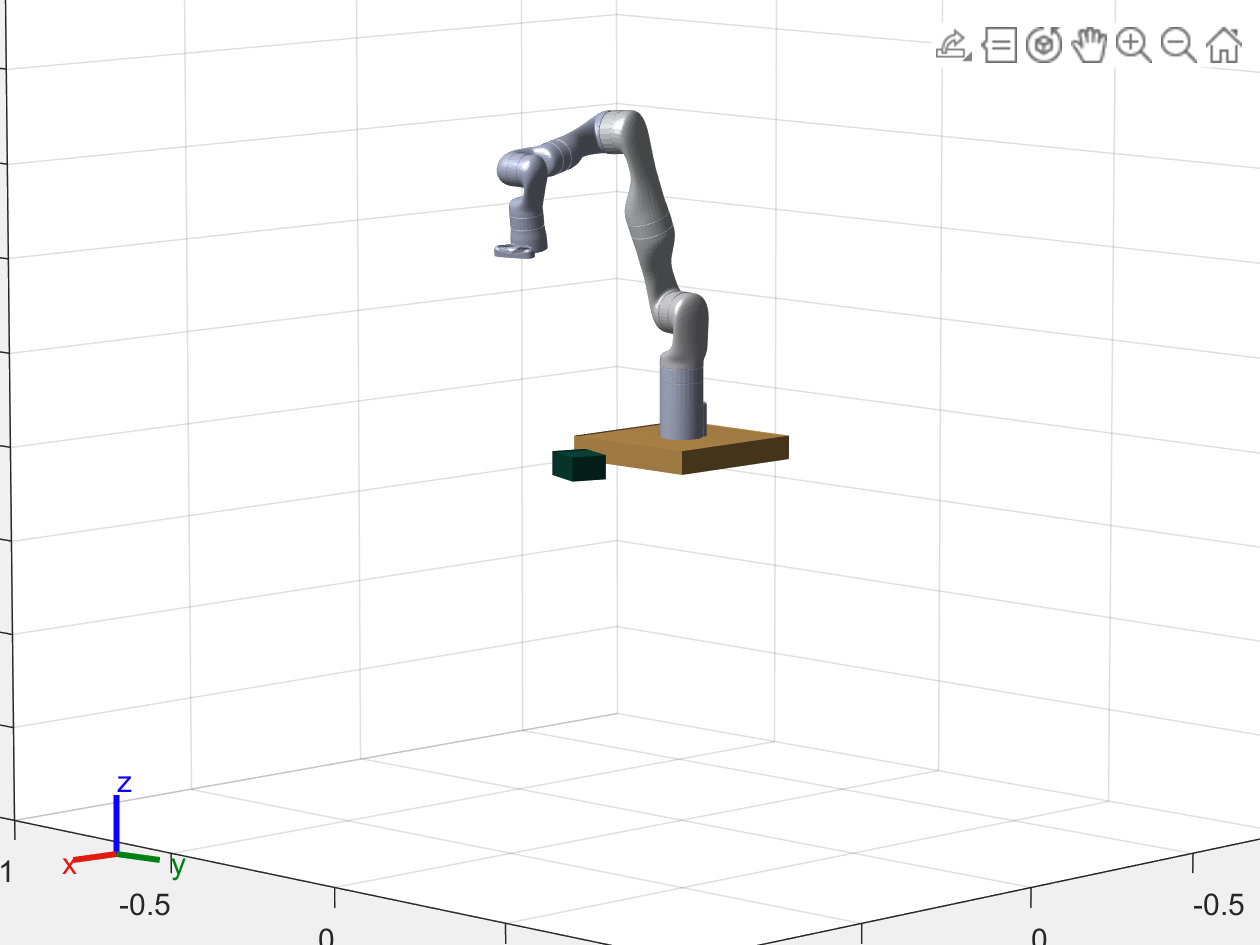

% Create bench mesh (X_length, Y_length, Z_length)
bench = collisionBox(.32, .32, 0.05); 

% Compute Homogeneous transformation matrix using translation vector at [x y z] position of the bench
% TBench = trvec2tform([0.35 0 -0.025]); 
TBench = trvec2tform([0 0 0]); 
bench.Pose = TBench;

% Height of the box in meter. 
boxHeight = .05;
% Position of the box in the base reference system [x y z]
boxPosition = [0.45 0.15 boxHeight/2]';
% Orientation of the box in degrees
boxOrientation = -20;  
% Box mesh (X_length, Y_length, Z_length)
box = collisionBox(0.075, 0.1, boxHeight); 
Rz = [cosd(boxOrientation) -sind(boxOrientation) 0; sind(boxOrientation) cosd(boxOrientation) 0; 0 0 1];

% Create 3x3 rotation matrix
transf = rotm2tform(Rz); 
% Homogeneous transformation(4x4) for the box
transf(:,4) = [boxPosition; 1]; 
box.Pose = transf;
% Creating a Box structure to be used in the next section to find pose transformation for visualization of the box object with the gripper
Box.mesh = box;  

% Create environment array of all collision objects
environmentWorld = {bench, box};

% Close the previous simulation figure window if it is present while running this script again
close(findobj('type','figure','name','Simulation of Gen3 to Detect and Pick Object'))

% Current figure handle
hFig = figure('name', 'Simulation of Gen3 to Detect and Pick Object');
% Current axes handle
ax = gca; 

show(gen3,testPose_Radmat,'PreservePlot',false,'FastUpdate',true,'Frames',"off");
set(gcf,'Visible','on');
hold on

% Initialize array for graphics objects
patchObj = gobjects(1,2); 
for i = 1:2
    [~,patchObj(i)] = show(environmentWorld{i});
end
patchObj(1).FaceColor = [0.89 0.68 0.37];
patchObj(2).FaceColor = [0.04 0.321 0.262];
axis([-0.8 1 -1 1 -0.8 1])
set(ax,'units','inch')
set(gca,'position',[0.5 0 5 5])
hold on;

find obj pos

frame = imread('Test_Img.png');

% % % % % % % % % Convert to HSV color space
% % % % % % % % hsvFrame = rgb2hsv(frame);
% % % % % % % % 
% % % % % % % % % Define red color threshold (adjust values if necessary)
% % % % % % % % redMask = (hsvFrame(:,:,1) > 0.9 | hsvFrame(:,:,1) < 0.1) & ... % Hue range for red
% % % % % % % %           (hsvFrame(:,:,2) > 0.4) & (hsvFrame(:,:,3) > 0.4);  % Saturation & Value conditions
% % % % % % % % 
% % % % % % % % % Find bounding boxes for detected objects
% % % % % % % % props = regionprops(redMask, 'BoundingBox');
% % % % % % % % 
% % % % % % % % % Find the biggest bounding box
% % % % % % % % if ~isempty(props)
% % % % % % % %     maxArea = 0;
% % % % % % % %     biggestBox = [];
% % % % % % % % 
% % % % % % % %     for i = 1:length(props)
% % % % % % % %         bbox = props(i).BoundingBox;
% % % % % % % %         area = bbox(3) * bbox(4); % width * height
% % % % % % % % 
% % % % % % % %         if area > maxArea
% % % % % % % %             maxArea = area;
% % % % % % % %             biggestBox = bbox;
% % % % % % % %         end
% % % % % % % %     end
% % % % % % % % end
% % % % % % % % bbox
tag2baseTform=pid_control_cameraCaliberation(gen3,testPose_Deg,frame)

tag2baseTform =    -0.0299    0.9352   -0.3529    0.3450
    0.9955   -0.0039   -0.0946    0.0864
   -0.0898   -0.3542   -0.9309   -0.0558
         0         0         0    1.0000


Cube_pose_base=[tag2baseTform(1,4) (tag2baseTform(2,4)) tag2baseTform(3,4)];


update simulation env

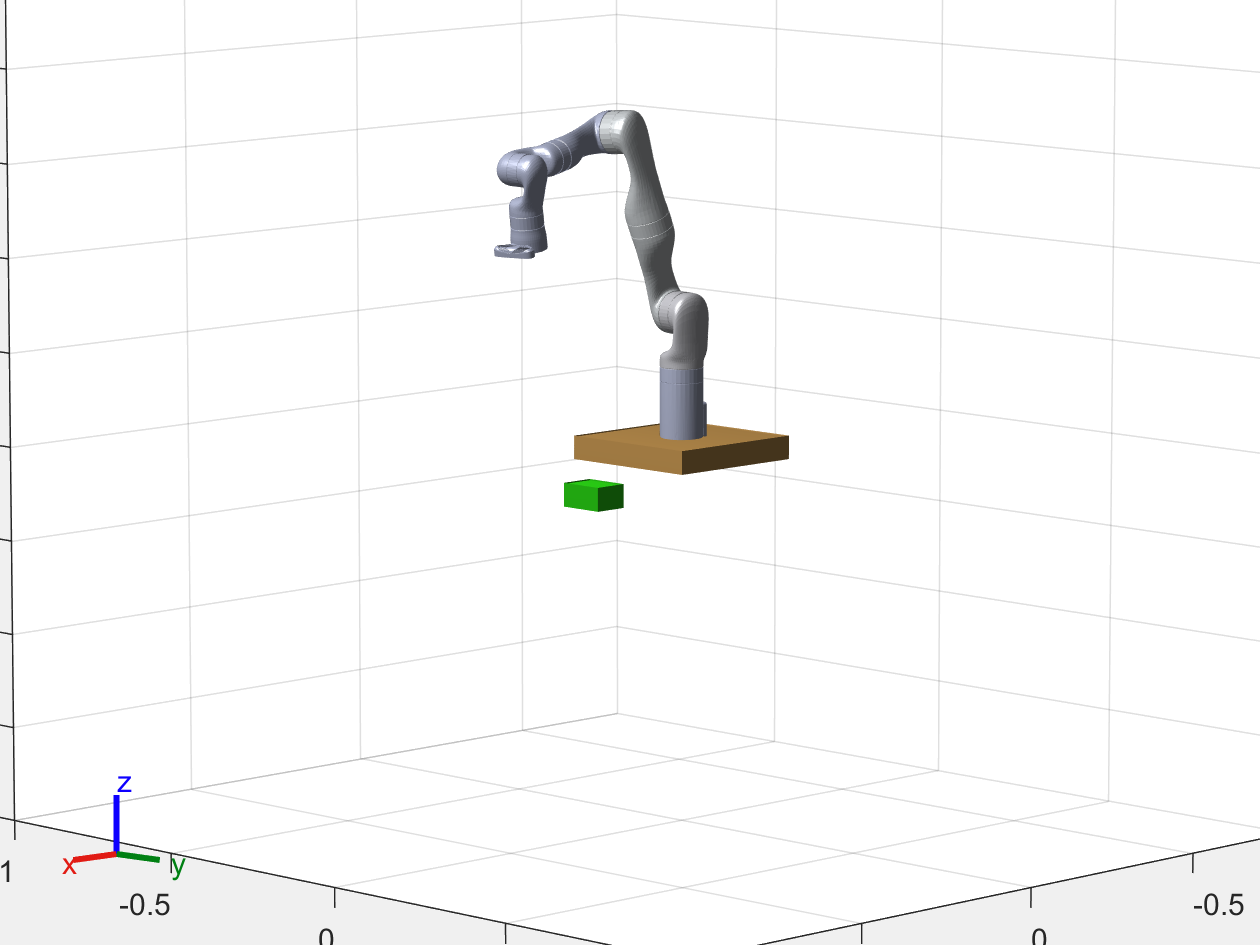

boxCenterPoint=Cube_pose_base;
boxPosition = [boxCenterPoint(1) boxCenterPoint(2) boxCenterPoint(3)]'; 
% Orientation of the box in degrees
boxOrientation = 0; 
Rz = [cosd(boxOrientation) -sind(boxOrientation) 0; sind(boxOrientation) cosd(boxOrientation) 0; 0 0 1];
% Create 3x3 rotation matrix
transf = rotm2tform(Rz); 

% Homogeneous transformation(4x4) for the box
transf(:,4) = [boxPosition; 1]; 
% Updating pose
box.Pose = transf; 

% Note: If you want to update the object dimension as per the actual
% object, then update it here by changing box.X, box.Y, box.Z parameter
% values. 

% Delete previous box patch object
delete(patchObj(2));

% Create new patch object with updated box parameters

[~,patchObj(2)] = show(box);
patchObj(2).FaceColor = [.2 1 .1];

generate trajectory

% Define the sample time and trajectory time array (For simulation
% purpose, we are using the same trajectory time for all the three tasks)

waypointTimes = [0;10];
% Sample time
ts = 0.25; %changing this from .2 to .001
% Creating a trajectory time array
trajTimes = waypointTimes(1):ts:waypointTimes(end);

reachToHeight = 0.3+.0615; 

goalPointForTask1 = boxCenterPoint' + [0;0;reachToHeight];
% goalPointForTask1= Cube_pose_base(1:3,4) +[0 0 .05]'

current_ee_pose=getTransform(gen3,testPose_Radmat,"EndEffector_Link")*[0;0;0;1];

waypointForTask1 = horzcat(current_ee_pose(1:3),goalPointForTask1)

waypointForTask1 =     0.4323    0.3450
   -0.0130    0.0864
    0.4593    0.3057


% Orientation at grasp pose
orientationAtGraspPose = -20; 
orientations = [-pi/2 pi 0; wrapToPi(deg2rad(orientationAtGraspPose)) pi 0]'

orientations =    -1.5708   -0.3491
    3.1416    3.1416
         0         0



ikInitGuess = testPose_Radmat'

ikInitGuess =     0.1063    0.3731    6.0614    1.3773    3.2529    4.7086    1.7212



numJoints = numel(testPose_Radmat);
jointLimits = zeros(numJoints, 2);
for j = 1:numJoints
    jointLimits(j, :) = gen3.Bodies{j}.Joint.PositionLimits;
end

**planPath - Use PID**

% computedTrajForTask1 = exampleHelperGenerateTrajectory(gen3,waypointForTask1,orientations,trajTimes,waypointTimes,ikInitGuess)
computedTrajForTask1 = tryingPID(gen3,waypointForTask1,orientations,trajTimes,waypointTimes,ikInitGuess,jointLimits,testPose_Radmat);

ikInitGuess =     0.1063    0.3731   -0.2218    1.3773   -3.0303   -1.5746    1.7212


tgtPose =    -0.0000    1.0000    0.0000    0.4323
    1.0000    0.0000   -0.0000   -0.0130
   -0.0000         0   -1.0000    0.4593
         0         0         0    1.0000


tgtPose =    -0.9397    0.3420    0.0000    0.3450
    0.3420    0.9397   -0.0000    0.0864
   -0.0000         0   -1.0000    0.3057
         0         0         0    1.0000





vel=(180/pi)*computedTrajForTask1.velocities';
vel(1,:)=0;
vel(end,:)=0;
vel=(vel');
acc=(180/pi)*computedTrajForTask1.acceleration';
acc(1,:)=0;
acc(end,:)=0;
acc=(acc');
qs_deg_correct=computedTrajForTask1.position*(180/pi);
timestamp=trajTimes';

visualize path

disp('---* Reaching 15cm above to the object*---');

---* Reaching 15cm above to the object*---


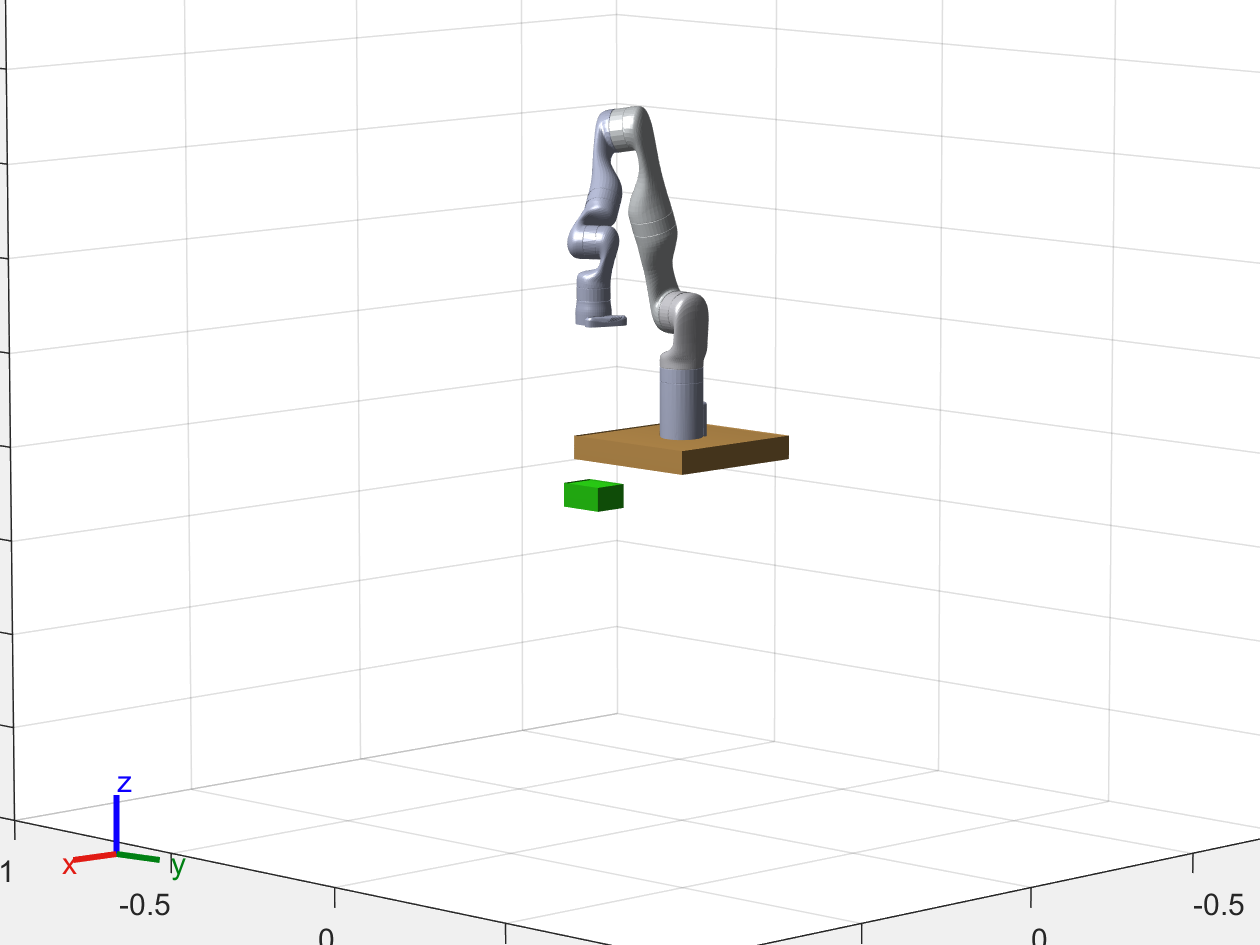

r = rateControl(1/ts);
for idx = 1:numel(trajTimes)
    config = computedTrajForTask1.position(:,idx)';
    show(gen3,config','PreservePlot',false,'FastUpdate',true,'Frames',"off");
    waitfor(r);
end

% Create a question dialog box for img capture
answer = questdlg('Send Traj to Robot:', ...
                 'Boolean Input', ...
                 'Yes', 'No', 'Yes');
                 
% Handle the response
switch answer
    case 'Yes'
        sndTraj = true;
    case 'No'
        sndTraj = false;
    otherwise
        % Handle case where user closes dialog without selecting
        sndTraj = []; % or some default value
end

# send commands to robot

Interpolate

if sndTraj==true

timestamp = 0:0.001:trajTimes(end);
qs_deg = interp1(trajTimes,qs_deg_correct.',timestamp);
vel = interp1(trajTimes,vel.',timestamp);
acc = interp1(trajTimes,acc.',timestamp);

Connect to robot

Simulink.importExternalCTypes('C:\Users\admin\OneDrive - North Carolina State University\Dr. Nitin Sharma\matlab_simplified_api_2.2.1\matlab_simplified_api_2.2.1\mex-wrapper\include\kortex_wrapper_data.h');
gen3Kinova = kortex();
gen3Kinova.ip_address = '192.168.1.10';
 
isOk = gen3Kinova.CreateRobotApisWrapper();
if isOk
   disp('You are connected to the robot!'); 
else
   error('Failed to establish a valid connection!'); 
end

Visualize the actual movement of the robot

title('Actual Movement of the Robot');
[~,~, actuatorFb, ~] = gen3Kinova.SendRefreshFeedback();
show(gen3, ((actuatorFb.position)*pi/180)','PreservePlot',false);

send robot to starting point of trajectory]

size(qs_deg,1);


jointCmd = wrapTo360(qs_deg(1,:));
constraintType = int32(0);
speed = 0;
duration = 0;
 

isOk = gen3Kinova.SendJointAngles(jointCmd, constraintType, speed, duration);
if isOk
    disp('success');
    
else
    disp('SendJointAngles cmd error');
    return;
end

**Check if the robot has reached the starting position**

while 1
    [isOk,~, actuatorFb, ~] = gen3Kinova.SendRefreshFeedback();
    show(gen3, ((actuatorFb.position)*pi/180)','PreservePlot',false);
    drawnow;
    if isOk
        if max(abs(wrapTo360(qs_deg(1,:))-actuatorFb.position)) < 0.1
            disp('Starting point reached.')
            break;
        end 
    else
        error('SendRefreshFeedback error')
    end
end

timestamp_2=timestamp';
size(timestamp_2,2);
numJoints = numel(testPose_Radmat);

## Send Pre-Computed Trajectory 


isOk = gen3Kinova.SendPreComputedTrajectory(qs_deg.', vel.', acc.', timestamp, size(timestamp,2));

if isOk
    disp('SendPreComputedTrajectory success');
else
    disp('SendPreComputedTrajectory command error');
end


**Check if the robot has reached the end position**

while 1
    [isOk,~, actuatorFb, ~] = gen3Kinova.SendRefreshFeedback();
    show(gen3, ((actuatorFb.position)*pi/180)','PreservePlot',false);
    drawnow;
    if isOk
        if max(abs(qs_deg(end,:)-actuatorFb.position)) < 0.1
            disp('End Point reached.')
            break;
        end 
    else
        error('SendRefreshFeedback error')
    end
end

## Disconnect from the Robot 

Use this command to disconnect from Kinova Gen3 robot Robot.

isOk = gen3Kinova.DestroyRobotApisWrapper();

Clear workspace

clear;


end